cd('/home/bholder/bit-matlab-sim')
addpath('/home/bholder/bit-matlab-sim/Miscellaneous')
addpath('/home/bholder/bit-matlab-sim/flexible_model_data/')
addpath('/home/bholder/bit-matlab-sim/Plant_functions/')
load_sl_glibc_patch

syms t1 t2 t3 t4 t5 t6 t7 t8 t9 real
syms dt1 dt2 dt3 dt4 dt5 dt6 dt7 dt8 dt9 real

zer = sym(0)

$$zer = 0$$


thet = [t1 t2 t3 t4 t5 t6 t7 t8 t9]'

$$thet = \left(\begin{array}{c} t_{1}\\ t_{2}\\ t_{3}\\ t_{4}\\ t_{5}\\ t_{6}\\ t_{7}\\ t_{8}\\ t_{9} \end{array}\right)$$

d_thet = [dt1; dt2; dt3; dt4; dt5; dt6; dt7; dt8; dt9];

z_n = sym([0.0, 1.0, 0.0, 1.0, 0.0, 0.0, 0.0, 1.0, 0.0;
       0.0, 0.0, 1.0, 0.0, 1.0, 0.0, 0.0, 0.0, 1.0;
       1.0, 0.0, 0.0, 0.0, 0.0, 1.0, 1.0, 0.0, 0.0])

$$z\_n = \left(\begin{array}{ccccccccc} 0 & 1 & 0 & 1 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 1 & 0 & 1 & 0 & 0 & 0 & 1\\ 1 & 0 & 0 & 0 & 0 & 1 & 1 & 0 & 0 \end{array}\right)$$


s7 = zeros(3,9);
for i = 1:9
    Cn = axis2rot_symb(z_n(:,i), thet(i));
    s7(:,i) = z_n(:,i);
    s7 = Cn*s7;    
end


s = zeros(3,9);
for i = 1:7
    Cn = axis2rot_symb(z_n(:,i), thet(i));
    s(:,i) = z_n(:,i);
    s = Cn*s;    
end

tau_y = sym('tau_y')

$$tau\_y = \tau_{y}$$

syms hs1 hs2 hs dhs1 dhs2 dhs real

h_s = [zer; zer; hs];
d_hs = [zer; zer; -tau_y];

% z7 = [0.01;0.015;1];
% z7 = z7/sqrt(z7'*z7)
z7 = z_n(:,7);


% d_hs = tau_rw*z7;

r = (s')*d_hs;

R = -(s') * xmat(h_s) * s;
R = simplify(R);

[ndof, g0, r_n1_n, z_n, p_n, m_n, c_n, ...
    i_n, m_w_n,  i_rw, bear_k_cst, bear_c_cst, k_d, b_d, ...
    w_rw_max, w_rw_nom, hs_rw, hs_rw_max, a_flex, b_flex, a_df, b_df] = init_func();

bear_k_cst = 62.6077


M = compute_mass_matrix_symb(thet, z_n, r_n1_n, m_w_n, p_n);

% Mb = zeros(6,6);
% Mb = M([1:3,7:9], [1:3, 7:9]);
% Mb = subs(Mb, t1, zer);
% Mb = subs(Mb, t6, zer);
% Mb = subs(Mb, t4, zer);
% Mb = subs(Mb, t5, zer);
% Mb_i = inv(Mb);

M = subs(M, t1, zer);
M = subs(M, t2, zer);
M = subs(M, t3, zer);
% 
% M6 = M(4:9, 4:9);
% M6i = inv(M6);

M = subs(M, t4, zer);
M = subs(M, t5, zer);
M = subs(M, t6, zer);
M = subs(M, t7, zer);

Mi = inv(M);

Pot = compute_potential_energy_term_symb(thet, c_n, z_n, m_n, r_n1_n, g0);

% 
spring = k_d.*thet;

syms tau_p tau_r tau_piv

tau = sym(zeros(9,1));
% tau(6) = tau_piv;
tau(8) = tau_r;
tau(9) = tau_p;



md = Mi*(tau-(R*d_thet)-r-spring-Pot);
mod = md(7:9);
% mod = md;
% mod = md(4:9);
% mod(1) = md(2) + md(4);12
% mod(2) = md(3) + md(5);
% 
% A_pend = [diff(mod, t6), diff(mod, t7), ...
%     diff(mod, t8), diff(mod, t9),...
%     diff(mod, dt6),   ...
%     diff(mod, dt7),  diff(mod, dt8), diff(mod, dt9),diff(mod, hs)];
% 
A_pend = [diff(mod, t7), ...
    diff(mod, t8), diff(mod, t9),...
    diff(mod, dt7),  diff(mod, dt8), diff(mod, dt9)];

% mod2 = [mod(6); mod(7); mod(8); mod(9)]
% mod = mod2;
% A_pend2 = [diff(mod, t6), diff(mod, t7), ...
%     diff(mod, t8), diff(mod, t9), diff(mod, dt6),   ...
%     diff(mod, dt7),  diff(mod, dt8), diff(mod, dt9),diff(mod, hs)];


% A_gond = A_pend(7:9, 13:19);
A_gond = A_pend;

A_gond = subs(A_gond, t1, zer);
A_gond = subs(A_gond, t2, zer);
A_gond = subs(A_gond, t3, zer);
A_gond = subs(A_gond, t4, zer);
A_gond = subs(A_gond, t5, zer);
A_gond = subs(A_gond, t6, zer);
A_gond = subs(A_gond, t7, zer);
% A_gond = subs(A_gond, t8, 0.1);
% A_gond = subs(A_gond, t9, -0.4*180/pi);
A_gond = subs(A_gond, dt1, zer);
A_gond = subs(A_gond, dt2, zer);
A_gond = subs(A_gond, dt3, zer);
A_gond = subs(A_gond, dt4, zer);
A_gond = subs(A_gond, dt5, zer);
A_gond = subs(A_gond, dt6, zer);
A_gond = subs(A_gond, dt7, zer);
A_gond = subs(A_gond, dt8, zer);
A_gond = subs(A_gond, dt9, zer);

% A_gond = subs(A_gond, hs, 2*pi*4.5);
% A_gond = subs(A_gond, hs2, zer);
% A_gond = subs(A_gond, dhs1, zer);
% A_gond = subs(A_gond, dhs2, zer);
% A_gond = vpa(simplify(A_gond),2)

B_pend = [diff(mod, tau_y), diff(mod, tau_r), diff(mod, tau_p)];

B_gond = B_pend;

B_gond = subs(B_gond, t1, zer);
B_gond = subs(B_gond, t2, zer);
B_gond = subs(B_gond, t3, zer);
B_gond = subs(B_gond, t4, zer);
B_gond = subs(B_gond, t5, zer);
% B_gond = subs(B_gond, t6, zer);
% B_gond = subs(B_gond, t7, zer);
% B_gond = subs(B_gond, t8, zer);
% B_gond = subs(B_gond, t9, zer);
B_gond = subs(B_gond, dt1, zer);
B_gond = subs(B_gond, dt2, zer);
B_gond = subs(B_gond, dt3, zer);
B_gond = subs(B_gond, dt4, zer);
B_gond = subs(B_gond, dt5, zer);
B_gond = subs(B_gond, dt6, zer);
B_gond = subs(B_gond, dt7, zer);
B_gond = subs(B_gond, dt8, zer);
B_gond = subs(B_gond, dt9, zer);

% B_gond = subs(B_gond, hs, 2*pi*4.5);
B_gond = subs(B_gond, hs2, zer);
B_gond = subs(B_gond, dhs1, zer);
B_gond = subs(B_gond, dhs2, zer);
% B_gond = vpa(simplify(B_gond),2)

roll_torque = 0.1*k_d(8);

Ap = subs(A_gond, t7, zer);
Ap = subs(Ap, t8, 0.1);
Ap = subs(Ap, t9, -40*pi/180);
Ap = subs(Ap, tau_p, zer);
Ap = subs(Ap, tau_y, zer);
Ap = subs(Ap, tau_piv, zer);
Ap = subs(Ap, tau_r, roll_torque);
Ap = subs(Ap, hs, 2*pi*4.5);


An = subs(A_gond, t7, 0);
An = subs(An, t8, 0.1);
An = subs(An, t9, -0.7);
An = subs(An, tau_p, zer);
An = subs(An, tau_y, zer);
An = subs(An, tau_r, -roll_torque);
An = subs(An, hs, 2*pi*4.5);

A_neg1 = vpa(An, 4);
A_pos1 = vpa(Ap, 4);

% vpa((An + Ap)/2, 4);

Bp = subs(B_gond, t7, zer);
Bp = subs(Bp, t8, 0.1);
Bp = subs(Bp, t9, -40*pi/180);
% Bp = subs(Bp, tau_p, zer);
% Bp = subs(Bp, tau_rw, zer);
% Bp = subs(Bp, tau_r, roll_torque);

B_pos1 = vpa(Bp, 4);

Bn = subs(B_gond, t7, zer);
Bn = subs(Bn, t8, -0.1);
Bn = subs(Bn, t9, -40*pi/180);
% Bp = subs(Bp, tau_p, zer);
% Bp = subs(Bp, tau_rw, zer);
% Bp = subs(Bp, tau_r, roll_torque);

B_neg1 = vpa(Bn, 4);

[S9, S8, S7] = compute_s_mat_symb(thet, z_n)

S_c = sym(zeros(3,9));

S_c(1,:) = S7(3,:);
S_c(2,:) = S8(1,:);
S_c(3,:) = S9(2,:);


S_c = subs(S_c, t1, 0);
S_c = subs(S_c, t2, 0);
S_c = subs(S_c, t3, 0);
S_c = subs(S_c, t4, 0);
S_c = subs(S_c, t5, 0);
S_c = subs(S_c, t6, 0);
S_c = subs(S_c, t7, 0);

% S_cp = subs(S_c, t8, 0.1);
S_cp = subs(S_c, t9, -40*pi/180);

ang_vel_p = S_cp*d_thet;
S = S_cp(:,7:9);
S = subs(S,t8, 0.1)

$$S = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ \sin\left(\frac{1}{10}\right) & 0 & 1 \end{array}\right)$$

S = eval(S);


StS_p = S'*S;
c_ss_p = zeros(5,6);
c_ss_p(1,4:6) = StS_p(1, :);
c_ss_p(2,4:6) = StS_p(2, :);
c_ss_p(3,4:6) = StS_p(2, :);
c_ss_p(4,4:6) = StS_p(3, :);
c_ss_p(5,4:6) = StS_p(3, :);



a_ss_p = zeros(6,6);
a_ss_p(1:3, 4:6) = eye(3);
a_ss_p(4:6, :) = eval(Ap);

b_ss_p = zeros(6,5);
%%% build b mats here
% yaw bow port
B_temp1 = eval(Bp);
% yaw stern sb
B_temp2 = eval(Bp);
b_ss_p(4:6,1) = B_temp1(:,1);
b_ss_p(4:6,2) = B_temp1(:,2);
b_ss_p(4:6,3) = B_temp2(:,2);
b_ss_p(4:6,4) = B_temp1(:,3);
b_ss_p(4:6,5) = B_temp2(:,3);

%Add stiffness termsm
m79 = Mi(7:9,7:9);
m79 = eval(subs(m79, [t7, t8, t9], [0, 0.1, -40*pi/180]))

m79 =     1.0010    0.0000   -0.0001
    0.0000    0.0042   -0.0000
   -0.0001   -0.0000    0.0083


kp = diag([100, 200, 100]);
kd = diag([1000, 2000, 1000]);

kp = diag([3000, 6000, 1500]);
kd = diag([1950, 2200, 7000]);

stiffness = m79*-kp*StS_p;
damping = m79*-kd*StS_p;

temp_k = a_ss_p(4:6,1:3);
temp_k = temp_k + stiffness;
a_ss_p(4:6,1:3) = temp_k;
a_ss_p(4:6,4:6) = damping;

% a_ss_p(3,3) = -0.0001;

sys = ss(a_ss_p, b_ss_p, c_ss_p, 0);
% [g,h1] = isPassive(sys)

% dlmwrite('lqr_a_3.csv', (a_ss_p), 'precision', '%.16f')
% dlmwrite('lqr_b_3.csv',(b_ss_p), 'precision', '%.16f')

Sn = S_cp(:,7:9);
Sn = subs(Sn,t8, -0.1)

$$Sn = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ -\sin\left(\frac{1}{10}\right) & 0 & 1 \end{array}\right)$$

Sn = eval(Sn);
StS_n = Sn'*Sn;


a_ss_n = zeros(6,6);
a_ss_n(1:3, 4:6) = eye(3);
a_ss_n(4:6, :) = eval(An);

m79 = Mi(7:9,7:9);
m79 = eval(subs(m79, [t7, t8, t9], [0, -0.1, -40*pi/180]))

m79 =     1.0010    0.0000    0.0001
    0.0000    0.0042    0.0000
    0.0001    0.0000    0.0083



stiffness = m79*-kp*StS_n;
damping = m79*-kd*StS_n;

temp_k = a_ss_n(4:6,1:3);
temp_k = temp_k + stiffness;
a_ss_n(4:6,1:3) = temp_k;
a_ss_n(4:6,4:6) = damping;


c_ss_n = zeros(5,6);
c_ss_n(1,4:6) = StS_n(1, :);
c_ss_n(2,4:6) = StS_n(2, :);
c_ss_n(3,4:6) = StS_n(2, :);
c_ss_n(4,4:6) = StS_n(3, :);
c_ss_n(5,4:6) = StS_n(3, :);

b_ss_n = zeros(6,5);
B_temp = eval(Bn)*StS_n;
b_ss_n(4:6,1) = B_temp(:,1);
b_ss_n(4:6,2) = B_temp(:,2);
b_ss_n(4:6,3) = B_temp(:,2);
b_ss_n(4:6,4) = B_temp(:,3);
b_ss_n(4:6,5) = B_temp(:,3);


aflex = a_mf_func;
bflex = b_mf_func;

num_modes = 4;

num_states = 6 + num_modes*2; 

a_pos_full = zeros(num_states,num_states);

a_pos_full(1:6,1:6) = a_ss_p;
a_pos_full(7:num_states, 7:num_states) = aflex(1:(2*num_modes), 1:(2*num_modes));

b_pos_full = zeros(num_states, 5);
b_pos_full(1:6,:) = b_ss_p;
b_pos_full(7:num_states,:) = bflex(1:(2*num_modes), :);
% b_temp1(:,1) = b_temp(:,1);
% b_temp1(:,2) = b_temp(:,2);
% b_temp1(:,3) = b_temp(:,4);
% b_temp1 = b_temp1 * StS_p;
% 
% b_temp2(:,1) = b_temp(:,1);
% b_temp2(:,2) = b_temp(:,3);
% b_temp2(:,3) = b_temp(:,5);
% b_temp2 = b_temp2*StS_p;
% 
% b_temp3(:,1) = b_temp(:,1);
% b_temp3(:,2) = b_temp(:,3);
% b_temp3(:,3) = b_temp(:,4);
% b_temp3 = b_temp3*StS_p;
% 
% b_temp4(:,1) = b_temp(:,1);
% b_temp4(:,2) = b_temp(:,2);
% b_temp4(:,3) = b_temp(:,5);
% b_temp4 = b_temp4*StS_p;
% 
% b_tot = zeros(num_modes*2,3,4);
% b_tot(:,:,1) = b_temp1;
% b_tot(:,:,2) = b_temp2;
% b_tot(:,:,3) = b_temp3;
% b_tot(:,:,4) = b_temp4;
% 
% 
% b_pos_full(7:num_states, 1) = mean([b_temp1(:,1), b_temp2(:,1)],2);
% b_pos_full(7:num_states, 2) = b_temp1(:,2);
% b_pos_full(7:num_states, 3) = b_temp2(:,2);
% b_pos_full(7:num_states, 4) = b_temp1(:,3);
% b_pos_full(7:num_states, 5) = b_temp2(:,3);

yaw_flx_vel = mean([b_temp1(:,1), b_temp2(:,1)],2);
bow_flx_vel= b_temp1(:,2);
stern_flx_vel = b_temp2(:,2);
port_flx_vel = b_temp1(:,3);
sb_flx_vel = b_temp2(:,3);

c_flex_vel = b_pos_full(7:num_states,:)'

c_flex_vel =          0    0.0084         0    0.0066         0   -0.0046         0   -0.0012
         0   -0.0203         0   -0.0192         0   -0.0503         0    0.0002
         0    0.0097         0   -0.0116         0   -0.0112         0    0.0000
         0   -0.0032         0    0.0081         0    0.0063         0   -0.0121
         0    0.0048         0   -0.0069         0   -0.0080         0   -0.0120


c_flex_pos = c_flex_vel;
c_flex_pos(:,1)= [];
c_flex_pos(:,2*num_modes) = zeros(5,1);

b_flex_pos = c_flex_pos';


%wrapping flex contributions to kp and kd
sts_alph_vel = mean(b_tot,3)

sts_alph_vel =          0         0         0
    0.0084   -0.0053    0.0008
         0         0         0
    0.0066   -0.0154    0.0006
         0         0         0
   -0.0046   -0.0308   -0.0008
         0         0         0
   -0.0012    0.0001   -0.0121


sts_alph_pos = zeros(size(sts_alph_vel));
sts_alph_pos(1:(2*num_modes)-1, :) = sts_alph_vel(2:(2*num_modes),:)

sts_alph_pos =     0.0084   -0.0053    0.0008
         0         0         0
    0.0066   -0.0154    0.0006
         0         0         0
   -0.0046   -0.0308   -0.0008
         0         0         0
   -0.0012    0.0001   -0.0121
         0         0         0



kp_flx = -kp*sts_alph_pos';
kd_flx = -kd*sts_alph_vel';
pid_flx = kp_flx+kd_flx

pid_flx =   -25.1945  -16.3765  -19.9322  -12.9559   13.9064    9.0392    3.5515    2.3085
   31.8901   11.6930   92.4233   33.8885  184.6206   67.6942   -0.6390   -0.2343
   -1.1633   -5.4287   -0.8814   -4.1130    1.2727    5.9393   18.1417   84.6614



% a_pos_full(4:6, 7:num_states) = pid_flx

full_pid = [stiffness, damping, pid_flx]

full_pid = 1.0e+03 *

   -3.0330   -0.0002    0.2996   -1.9714   -0.0001    0.1941   -0.0252   -0.0164   -0.0199   -0.0130    0.0139    0.0090    0.0036    0.0023
   -0.0001   -0.0254    0.0000   -0.0001   -0.0093   -0.0000    0.0319    0.0117    0.0924    0.0339    0.1846    0.0677   -0.0006   -0.0002
    0.0009   -0.0000   -0.0124    0.0055   -0.0000   -0.0578   -0.0012   -0.0054   -0.0009   -0.0041    0.0013    0.0059    0.0181    0.0847


yaw_pid = full_pid(1,:)

yaw_pid = 1.0e+03 *

   -3.0330   -0.0002    0.2996   -1.9714   -0.0001    0.1941   -0.0252   -0.0164   -0.0199   -0.0130    0.0139    0.0090    0.0036    0.0023


roll_pid = full_pid(2,:)

roll_pid =    -0.1248  -25.3698    0.0102   -0.0802   -9.3023   -0.0020   31.8901   11.6930   92.4233   33.8885  184.6206   67.6942   -0.6390   -0.2343


pitch_pid = full_pid(3,:)

pitch_pid =     0.8876   -0.0086  -12.3656    5.5494   -0.0032  -57.8453   -1.1633   -5.4287   -0.8814   -4.1130    1.2727    5.9393   18.1417   84.6614



sts_alph_vel

sts_alph_vel =          0         0         0
    0.0084   -0.0053    0.0008
         0         0         0
    0.0066   -0.0154    0.0006
         0         0         0
   -0.0046   -0.0308   -0.0008
         0         0         0
   -0.0012    0.0001   -0.0121



pid_cont = zeros(2*num_modes, num_states);

for md = 1:num_modes
    rw = 2*md;
    tau_cont = zeros(1,num_states);
    tau_cont = tau_cont + sts_alph_vel(rw,1) * yaw_pid;
    tau_cont = tau_cont + sts_alph_vel(rw,2) * roll_pid;
    tau_cont = tau_cont + sts_alph_vel(rw,3) * pitch_pid;
    pid_cont(rw,:) = tau_cont;
end
pid_cont

pid_cont =          0         0         0         0         0         0         0         0         0         0         0         0         0         0
  -25.4702    0.1328    2.5067  -16.5512    0.0487    1.5849   -0.3820   -0.2039   -0.6593   -0.2921   -0.8635   -0.2793    0.0473    0.0863
         0         0         0         0         0         0         0         0         0         0         0         0         0         0
  -20.1489    0.3891    1.9834  -13.0934    0.1427    1.2554   -0.6593   -0.2921   -1.5566   -0.6105   -2.7507   -0.9792    0.0441    0.0687
         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   14.0624    0.7818   -1.3788    9.1360    0.2867   -0.8504   -0.8635   -0.2793   -2.7507   -0.9792   -5.7463   -2.1299   -0.0122   -0.0753
         0         0         0         0         0         0         0         0         0         0         0         0         0         0
  


% a_pos_full(7:num_states, :) = a_pos_full(7:num_states,:) + pid_cont

eig(a_pos_full)

ans = 1.0e+03 *

  -1.9704 + 0.0000i
  -0.0571 + 0.0000i
  -0.0015 + 0.0000i
  -0.0002 + 0.0000i
  -0.0047 + 0.0020i
  -0.0047 - 0.0020i
  -0.0001 + 0.0828i
  -0.0001 - 0.0828i
  -0.0001 + 0.0892i
  -0.0001 - 0.0892i



c_pos_full = zeros(5,num_states);
% c_pos_full(:,1:6) = c_ss_p;
% c_pos_full(:, 7:num_states) = b_pos_full(7:num_states, :)'

c_pos_full(:,1:3) = zeros(5, 3);
c_pos_full(:,4:6) = [1 0 0; 0 1 0; 0 1 0; 0 0 1; 0 0 1];
c_pos_full(:, 7:num_states) = bflex(1:2*num_modes, :)'

c_pos_full =          0         0         0    1.0000         0         0         0    0.0083         0    0.0066         0   -0.0046         0    0.0000
         0         0         0         0    1.0000         0         0   -0.0203         0   -0.0192         0   -0.0503         0    0.0002
         0         0         0         0    1.0000         0         0    0.0097         0   -0.0116         0   -0.0112         0    0.0000
         0         0         0         0         0    1.0000         0   -0.0040         0    0.0075         0    0.0068         0   -0.0121
         0         0         0         0         0    1.0000         0    0.0039         0   -0.0076         0   -0.0075         0   -0.0121


## negative mats

a_neg_full = zeros(num_states,num_states);

a_neg_full(1:6,1:6) = a_ss_n;
a_neg_full(7:num_states, 7:num_states) = aflex(1:(2*num_modes), 1:(2*num_modes));

b_neg_full = zeros(num_states, 5);
b_neg_full(1:6,:) = b_ss_n;
b_temp = bflex(1:(2*num_modes), :);
b_temp1(:,1) = b_temp(:,1);
b_temp1(:,2) = b_temp(:,2);
b_temp1(:,3) = b_temp(:,4);
b_temp1 = b_temp1 * StS_n;
% b_temp1 = StS_n * b_temp1;

b_temp2(:,1) = b_temp(:,1);
b_temp2(:,2) = b_temp(:,3);
b_temp2(:,3) = b_temp(:,5);
b_temp2 = b_temp2*StS_n;
% b_temp2 = StS_n*b_temp2;

b_temp3(:,1) = b_temp(:,1);
b_temp3(:,2) = b_temp(:,3);
b_temp3(:,3) = b_temp(:,4);
b_temp3 = b_temp3*StS_n;
% b_temp3 = StS_n*b_temp3;

b_temp4(:,1) = b_temp(:,1);
b_temp4(:,2) = b_temp(:,2);
b_temp4(:,3) = b_temp(:,5);
b_temp4 = b_temp4*StS_n;
% b_temp4 = StS_n*b_temp4;

b_tot = zeros(num_modes*2,3,4);
b_tot(:,:,1) = b_temp1;
b_tot(:,:,2) = b_temp2;
b_tot(:,:,3) = b_temp3;
b_tot(:,:,4) = b_temp4;

b_neg_full(7:num_states, 1) = mean([b_temp1(:,1), b_temp2(:,1)],2);
b_neg_full(7:num_states, 2) = b_temp1(:,2);
b_neg_full(7:num_states, 3) = b_temp2(:,2);
b_neg_full(7:num_states, 4) = b_temp1(:,3);
b_neg_full(7:num_states, 5) = b_temp2(:,3)

b_neg_full =          0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
    0.0010    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0042    0.0042   -0.0000   -0.0000
   -0.0007    0.0000    0.0000    0.0083    0.0083
         0         0         0         0         0
    0.0084   -0.0203    0.0097   -0.0049    0.0031
         0         0         0         0         0
    0.0067   -0.0192   -0.0116    0.0068   -0.0083



yaw_flx_vel = mean([b_temp1(:,1), b_temp2(:,1)],2);
bow_flx_vel= b_temp1(:,2);
stern_flx_vel = b_temp2(:,2);
port_flx_vel = b_temp1(:,3);
sb_flx_vel = b_temp2(:,3);

c_flex_vel = b_neg_full(7:num_states,:)'

c_flex_vel =          0    0.0084         0    0.0067         0   -0.0046         0    0.0012
         0   -0.0203         0   -0.0192         0   -0.0503         0    0.0002
         0    0.0097         0   -0.0116         0   -0.0112         0    0.0000
         0   -0.0049         0    0.0068         0    0.0072         0   -0.0121
         0    0.0031         0   -0.0083         0   -0.0071         0   -0.0121


c_flex_neg = c_flex_vel;
c_flex_neg(:,1)= [];
c_flex_neg(:,2*num_modes) = zeros(5,1);

b_flex_neg = c_flex_neg';


%wrapping flex contributions to kp and kd
sts_alph_vel = mean(b_tot,3)

sts_alph_vel =          0         0         0
    0.0084   -0.0053   -0.0009
         0         0         0
    0.0067   -0.0154   -0.0007
         0         0         0
   -0.0046   -0.0308    0.0001
         0         0         0
    0.0012    0.0001   -0.0121


sts_alph_neg = zeros(size(sts_alph_vel));
sts_alph_neg(1:(2*num_modes)-1, :) = sts_alph_vel(2:(2*num_modes),:)

sts_alph_neg =     0.0084   -0.0053   -0.0009
         0         0         0
    0.0067   -0.0154   -0.0007
         0         0         0
   -0.0046   -0.0308    0.0001
         0         0         0
    0.0012    0.0001   -0.0121
         0         0         0



kp_flx = -kp*sts_alph_pos';
kd_flx = -kd*sts_alph_vel';
pid_flx = kp_flx+kd_flx

pid_flx =   -25.1945  -16.3979  -19.9322  -12.9831   13.9064    8.8857    3.5515   -2.4014
   31.8901   11.6930   92.4233   33.8885  184.6206   67.6942   -0.6390   -0.2343
   -1.1633    6.2010   -0.8814    5.0912    1.2727   -0.4212   18.1417   84.6944



% a_neg_full(4:6, 7:num_states) = pid_flx;

full_pid = [stiffness, damping, pid_flx];
yaw_pid = full_pid(1,:);
roll_pid = full_pid(2,:);
pitch_pid = full_pid(3,:);

sts_alph_vel

sts_alph_vel =          0         0         0
    0.0084   -0.0053   -0.0009
         0         0         0
    0.0067   -0.0154   -0.0007
         0         0         0
   -0.0046   -0.0308    0.0001
         0         0         0
    0.0012    0.0001   -0.0121



pid_cont = zeros(2*num_modes, num_states);

for md = 1:num_modes
    rw = 2*md;
    tau_cont = zeros(1,num_states);
    tau_cont = tau_cont + sts_alph_vel(rw,1) * yaw_pid;
    tau_cont = tau_cont + sts_alph_vel(rw,2) * roll_pid;
    tau_cont = tau_cont + sts_alph_vel(rw,3) * pitch_pid;
    pid_cont(rw,:) = tau_cont;
end
pid_cont

pid_cont =          0         0         0         0         0         0         0         0         0         0         0         0         0         0
  -25.5051    0.1328    2.5306  -16.5821    0.0487    1.6832   -0.3803   -0.2055   -0.6581   -0.2938   -0.8654   -0.2847    0.0172   -0.0940
         0         0         0         0         0         0         0         0         0         0         0         0         0         0
  -20.1924    0.3892    2.0038  -13.1282    0.1427    1.3342   -0.6581   -0.2938   -1.5557   -0.6122   -2.7522   -0.9833    0.0203   -0.0740
         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   13.8245    0.7818   -1.3664    8.9859    0.2866   -0.8877   -0.8665   -0.2847   -2.7531   -0.9833   -5.7441   -2.1235    0.0046    0.0232
         0         0         0         0         0         0         0         0         0         0         0         0         0         0
  


% a_neg_full(7:num_states, :) = a_neg_full(7:num_states,:) + pid_cont

eig(a_neg_full)

ans = 1.0e+03 *

  -1.9704 + 0.0000i
  -0.0571 + 0.0000i
  -0.0015 + 0.0000i
  -0.0002 + 0.0000i
  -0.0047 + 0.0020i
  -0.0047 - 0.0020i
  -0.0001 + 0.0828i
  -0.0001 - 0.0828i
  -0.0001 + 0.0892i
  -0.0001 - 0.0892i


% 
% c_neg_full = zeros(5,num_states);
% c_neg_full(:,1:6) = c_ss_n;
% c_neg_full(:, 7:num_states) = b_neg_full(7:num_states, :)'
c_neg_full = c_pos_full;


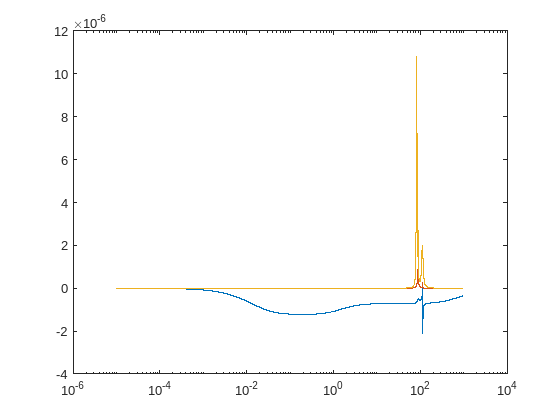


sys = ss(a_ss_n, b_ss_n, c_ss_n, 0);
% [g,h2] = isPassive(sys)
% 
% dlmwrite('lqr_a_3n.csv', (a_ss), 'precision', '%.16f')
% dlmwrite('lqr_b_3n.csv',(b_ss), 'precision', '%.16f')
% 

% a_ss_p(5,5) = -0.001; %roll damping
% a_ss_p(6,6) = -0.001; % pitch damping
% a_ss_p(4,4) = -0.001; % yaw damping
% a_ss_p(4,1) = -0.01; %yaw stiffness

[a1,b1] = ss2tf(a_pos_full,b_pos_full,c_pos_full,zeros(5,5),1);
[a2,b2] = ss2tf(a_pos_full,b_pos_full,c_pos_full,zeros(5,5),2);
[a3,b3] = ss2tf(a_pos_full,b_pos_full,c_pos_full,zeros(5,5),3);
[a4,b4] = ss2tf(a_pos_full,b_pos_full,c_pos_full,zeros(5,5),4);
[a5,b5] = ss2tf(a_pos_full,b_pos_full,c_pos_full,zeros(5,5),5);
% [a1,b1] = ss2tf(a_neg_full,b_neg_full,c_neg_full,zeros(5,5),1);
% [a2,b2] = ss2tf(a_neg_full,b_neg_full,c_neg_full,zeros(5,5),2);
% [a3,b3] = ss2tf(a_neg_full,b_neg_full,c_neg_full,zeros(5,5),3);
% [a4,b4] = ss2tf(a_neg_full,b_neg_full,c_neg_full,zeros(5,5),4);
% [a5,b5] = ss2tf(a_neg_full,b_neg_full,c_neg_full,zeros(5,5),5);

sys11 = tf(a1(1,:), b1);
sys21 = tf(a1(2,:), b1);
sys31 = tf(a1(3,:), b1);
sys41 = tf(a1(4,:), b1);
sys51 = tf(a1(5,:), b1);

sys12 = tf(a2(1,:), b2);
sys22 = tf(a2(2,:), b2);
sys32 = tf(a2(3,:), b2);
sys42 = tf(a2(4,:), b2);
sys52 = tf(a2(5,:), b2);

sys13 = tf(a3(1,:), b3);
sys23 = tf(a3(2,:), b3);
sys33 = tf(a3(3,:), b3);
sys43 = tf(a3(4,:), b3);
sys53 = tf(a3(5,:), b3);

sys14 = tf(a4(1,:), b4);
sys24 = tf(a4(2,:), b4);
sys34 = tf(a4(3,:), b4);
sys44 = tf(a4(4,:), b4);
sys54 = tf(a4(5,:), b4);

sys15 = tf(a5(1,:), b5);
sys25 = tf(a5(2,:), b5);
sys35 = tf(a5(3,:), b5);
sys45 = tf(a5(4,:), b5);
sys55 = tf(a5(5,:), b5);

sysmat = [sys11, sys12, sys13, sys14, sys15; ...
    sys21, sys22, sys23, sys24, sys25;...
    sys31, sys32, sys33, sys34, sys35;...
    sys41, sys42, sys43, sys44, sys45;...
    sys51, sys52, sys53, sys54, sys55];
omega = logspace(-5, 3, 300000); % Frequency range, adjust as needed

[h] = freqresp(sysmat, omega);
eg = zeros(5, length(h(1,1,:)));

for loc = 1:length(h(1,1,:))
    g = h(:,:,loc);
    herm = 0.5*(g + g');
    eg(:,loc) = eig(herm);
end

plot(omega, eg(1,:), omega, eg(2,:), omega, eg(3,:))
set(gca, 'XScale', 'log')


min(min(eg))

ans = -2.1316e-06



A_use = a_pos_full;
% A_use(12,5) = -0.0001;
B_use = b_pos_full;
C_use = c_pos_full;

qr = diag([1, 1, 1,...
           10000,20000, 10000,...
           1, 10,...
           1, 10,...
           1, 10,...
           1, 10]);

ql = diag([.1, .05, .1,...
           0.001, 0.01, 0.01,...
           10, 1,...
           10, 1, ...
           10, 1, ...
           10, 1]);

% ql = inv(qr)*10;
r_lqr = 1.00* diag([1, 1, 1, 1, 1]);
[K,P1,Pol] = lqr(A_use,B_use,qr,r_lqr,0);
Cc = K;
%% make closed loop A
Ac = A_use - (B_use * Cc);
P2 = lyap(Ac',ql);
Bc = inv(P2)*Cc';

cc_p = Cc;
bc_p = Bc;
ac_p = Ac;
A_pol = [A_use, -B_use*Cc; Bc*C_use, Ac];
eigc = eig(Ac);
eigf = eig(A_pol);
sort(eigc, 'ComparisonMethod', 'real')

ans = 1.0e+03 *

  -1.9704 + 0.0000i
  -0.0571 + 0.0000i
  -0.0047 - 0.0020i
  -0.0047 + 0.0020i
  -0.0015 + 0.0000i
  -0.0002 + 0.0000i
  -0.0001 - 0.1125i
  -0.0001 + 0.1125i
  -0.0001 - 0.1145i
  -0.0001 + 0.1145i


sort(eigf, 'ComparisonMethod', 'real')

ans = 1.0e+03 *

  -1.9705 + 0.0000i
  -1.9703 + 0.0000i
  -0.0571 - 0.0141i
  -0.0571 + 0.0141i
  -0.0085 - 0.0246i
  -0.0085 + 0.0246i
  -0.0015 + 0.0000i
  -0.0015 + 0.0000i
  -0.0007 - 0.0006i
  -0.0007 + 0.0006i


max(real(eigf))

ans = -0.0857


generate_rust_code_to_file('/home/bholder/gigabit_code/adcs/src/control/lqr/pos.rs', a_pos_full, b_pos_full, ac_p, bc_p, cc_p);

% [xout2, eigc, eigf] = opt_ql(a_ss_n, b_ss_n, c_ss_n, qr, r)

% ql = diag(xout2(1:13));
% r = diag(xout2(14:18));


A_use = a_neg_full;
% A_use(12,5) = -0.0001;
B_use = b_neg_full;
C_use = c_neg_full;

[K,P1,Pol] = lqr(A_use,B_use,qr,r_lqr,0);

Cc = K;

%% make closed loop A

Ac = A_use - (B_use * Cc);
eig(Ac)

ans = 1.0e+03 *

  -1.9704 + 0.0000i
  -0.0571 + 0.0000i
  -0.0001 + 0.1145i
  -0.0001 - 0.1145i
  -0.0001 + 0.1125i
  -0.0001 - 0.1125i
  -0.0001 + 0.0892i
  -0.0001 - 0.0892i
  -0.0001 + 0.0828i
  -0.0001 - 0.0828i



P2 = lyap(Ac',ql);

Bc = inv(P2)*Cc';

cc_n = Cc;
bc_n = Bc;
ac_n = Ac;
% 
% A_use = a_ss_n;
% % A_use(5,5) = -0.001;
% B_use = b_ss_n;
% C_use = c_ss_n;

A_pol = [A_use, -B_use*Cc; Bc*C_use, Ac];

eigc = eig(Ac);
eigf = eig(A_pol);
max(real(eigf))

ans = -0.0857



sort(eigc, 'ComparisonMethod', 'real')

ans = 1.0e+03 *

  -1.9704 + 0.0000i
  -0.0571 + 0.0000i
  -0.0047 - 0.0020i
  -0.0047 + 0.0020i
  -0.0015 + 0.0000i
  -0.0002 + 0.0000i
  -0.0001 - 0.1125i
  -0.0001 + 0.1125i
  -0.0001 - 0.1145i
  -0.0001 + 0.1145i


sort(eigf, 'ComparisonMethod', 'real')

ans = 1.0e+03 *

  -1.9705 + 0.0000i
  -1.9703 + 0.0000i
  -0.0571 - 0.0141i
  -0.0571 + 0.0141i
  -0.0085 - 0.0246i
  -0.0085 + 0.0246i
  -0.0015 + 0.0000i
  -0.0015 + 0.0000i
  -0.0007 - 0.0006i
  -0.0007 + 0.0006i



generate_rust_code_to_file('/home/bholder/gigabit_code/adcs/src/control/lqr/neg.rs', a_neg_full, b_neg_full, ac_n, bc_n, cc_n);


% eig_sys = [];
% eig_obs = [];
% tol = 6;
% 
% for loc = 1:length(eigf)
%     val = eigf(loc);
%     for loc2 = 1:length(eigc)
%         val2 = eigc(loc2);
% 
%         rl = real(val);
%         cm = imag(val);
%         rl2 = real(val2);
%         cm2 = imag(val2);
% 
%         rl_mag = abs(rl - rl2)/abs(min(abs(rl),abs(rl2)));
%         im_mag = abs(cm - cm2)/abs(min(abs(cm),abs(cm2)));
% 
%         if rl_mag < tol
%             if im_mag < tol
%                 eig_sys = [eig_sys, val];
%             end
%         end
%     end
% end
% eig_sys'



% A = Ap_tot';
% B = Bp_tot;
% R = r;
% Q = qr;
% 
% Z = [A -B/R*B.';-Q -A.'];
% 
% [V,D] = eig(Z);
% eigvals = diag(D);
% % Take only eigenvalues less than 0 as the basis
% eigvalsmask = real(eigvals)<0;
% n = size(A,1);
% negV = zeros(2*n,n);
% negV2 = negV;
% 
% cnt = 0;
% 
% for i = 1:2*n
%     if(eigvalsmask(i)>0)
%         cnt = cnt+1
%         negV(:,cnt) = V(:,i);
%     end
% end
% 
% U11 = negV(1:n,:);        
% U21 = negV(n+1:2*n,:);
% 
% P = (U21/U11);
% 
% negV2 = negV
% negV2(:,2) = negV(:,3);
% negV2(:,3) = negV(:,2);
% negV2
% negV
% U11 = negV2(1:n,:);
% U21 = negV2(n+1:2*n,:);
% P2 = (U21/U11);
